# Forced Damped Double-Well Oscillator

## Strogatz section 12.5

in 1979, Moon & Holmes studied the forced damped double-well oscillator


$$\ddot{x} + \delta \dot{x} - x + x^3 = F \cos{\omega t}$$


In this demonstration we fix $\delta=\frac14$ and $\omega=1$

First we show that for sm

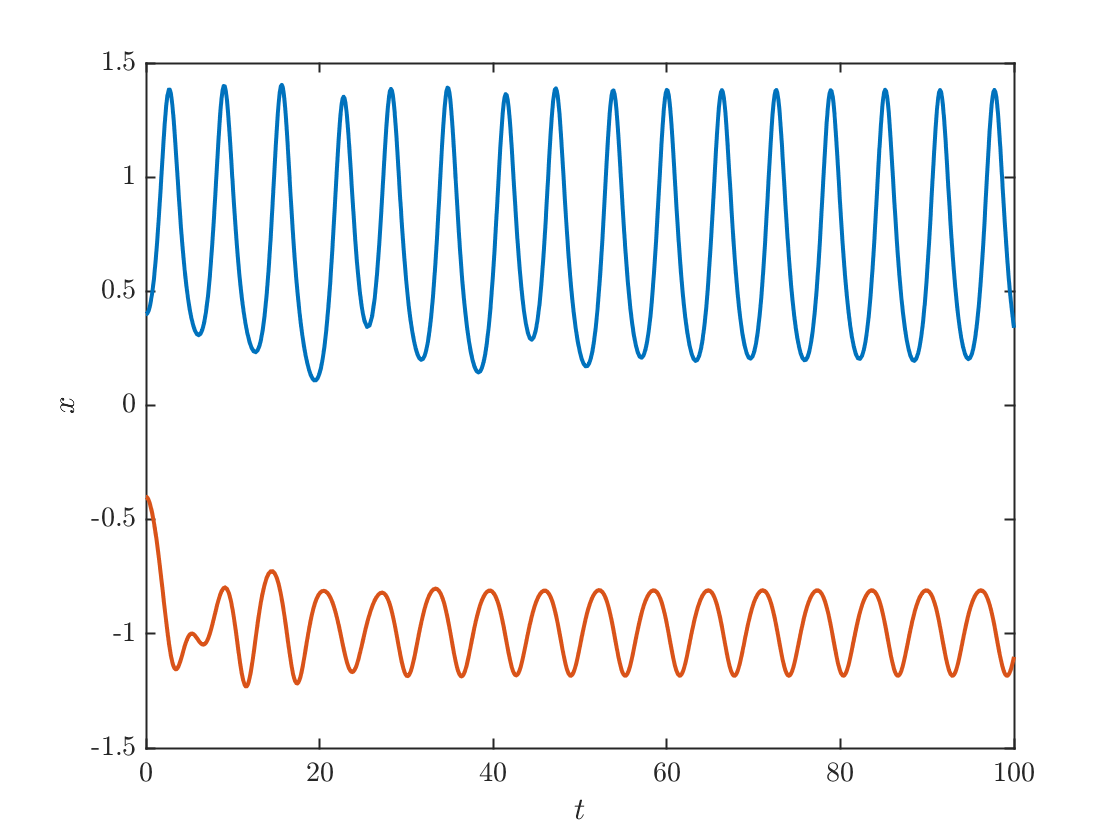

clf;hold off
delta=1/4;
omega=1;
F=0.18;
myODE=@(t,y)(doublewellODE(t,y,delta,F,omega));
tFinal=100; 
[tPlus,yPlus]=ode45(myODE,[0 tFinal],[.4;0]);
[tMinus,yMinus]=ode45(myODE,[0 tFinal],[-.4;0]);
plot(tPlus,yPlus(:,1),tMinus,yMinus(:,1));xlabel('$t$');ylabel('$x$')

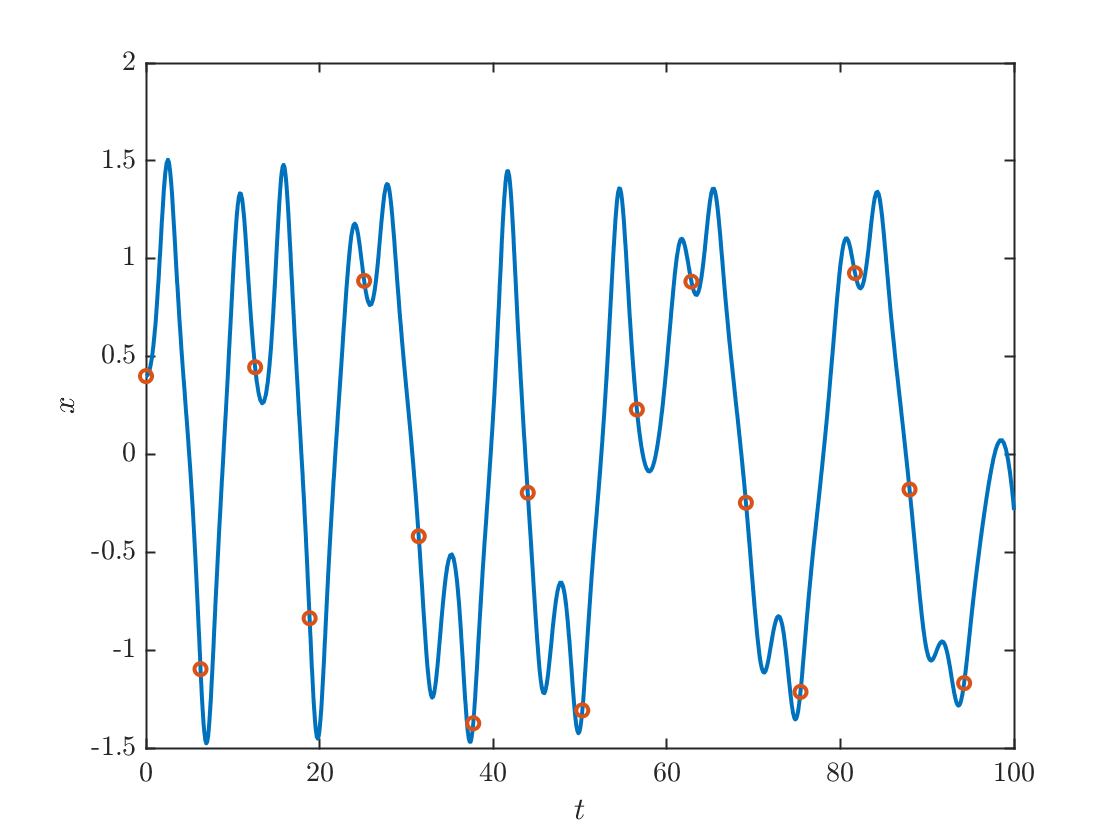

F=0.4;
myODE=@(t,y)(doublewellODE(t,y,delta,F,omega));
myEvent=@(t,y)doublewellEvent(t,y,omega);
options=odeset('Events',myEvent);
[t,y,te,ye]=ode45(myODE,[0 tFinal],[.4;0],options);
plot(t,y(:,1),te,ye(:,1),'o');xlabel('$t$');ylabel('$x$')

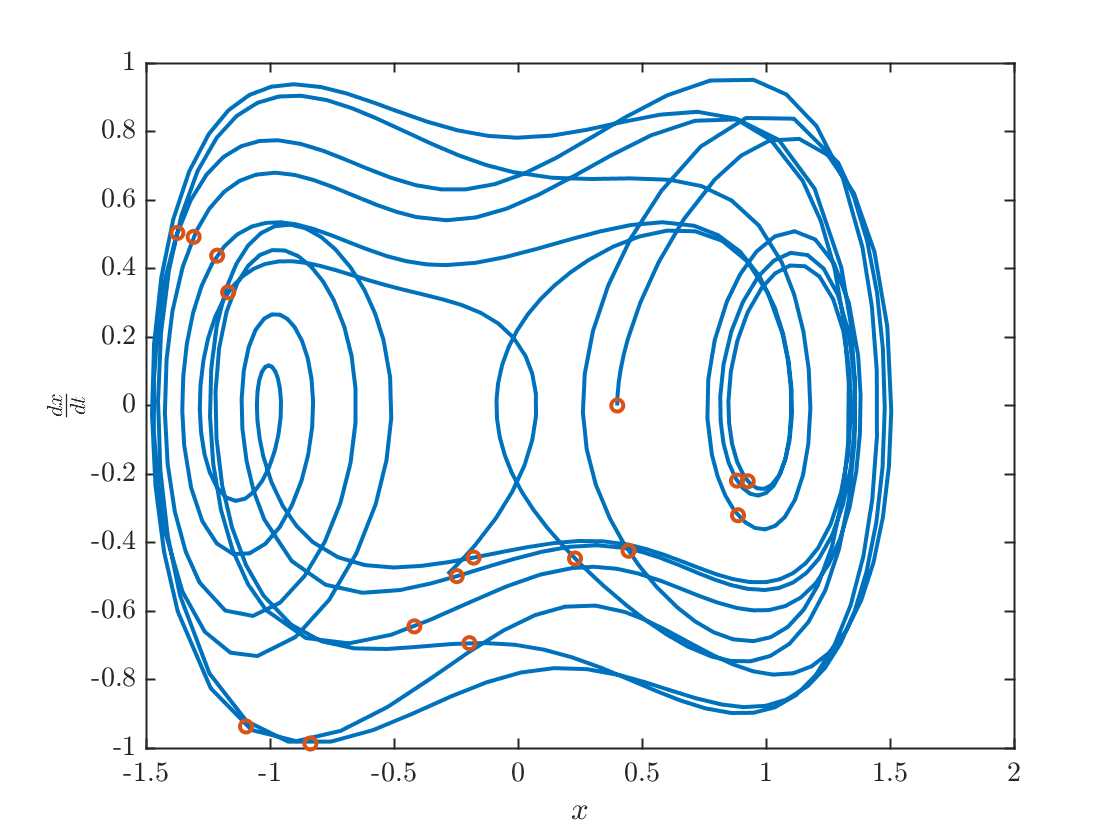

plot(y(:,1),y(:,2),ye(:,1),ye(:,2),'o')
xlabel('$x$');ylabel('$\frac{dx}{dt}$')

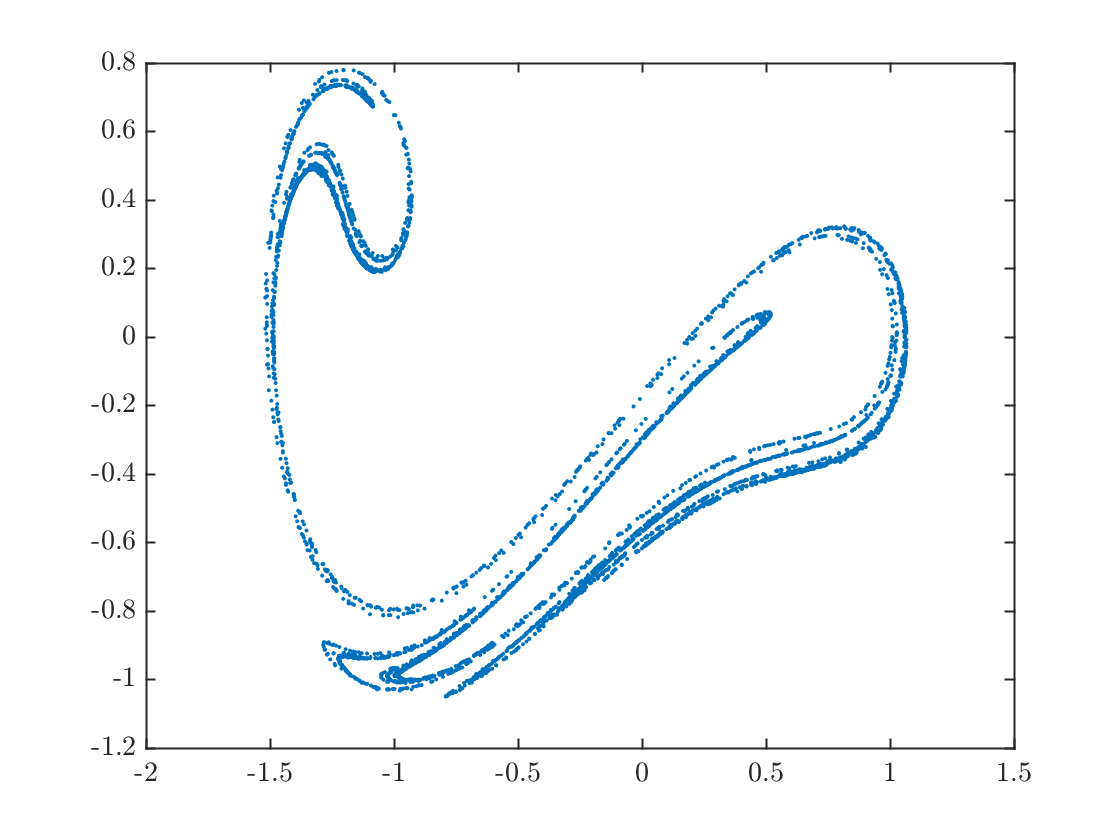

tFinal=5000*2*pi;
tTransient=10*2*pi;
myEvent=@(t,y)doublewellEvent(t,y,omega);
options=odeset('Events',myEvent);
[~,~,te,ye]=ode45(myODE,[0 tTransient+tFinal],[.4,0],options);
p=find(te>tTransient,1,'first');
ye=ye(p:end,:);
x=ye(:,1);y=ye(:,2);
plot(x,y,'.')

## Box-counting step

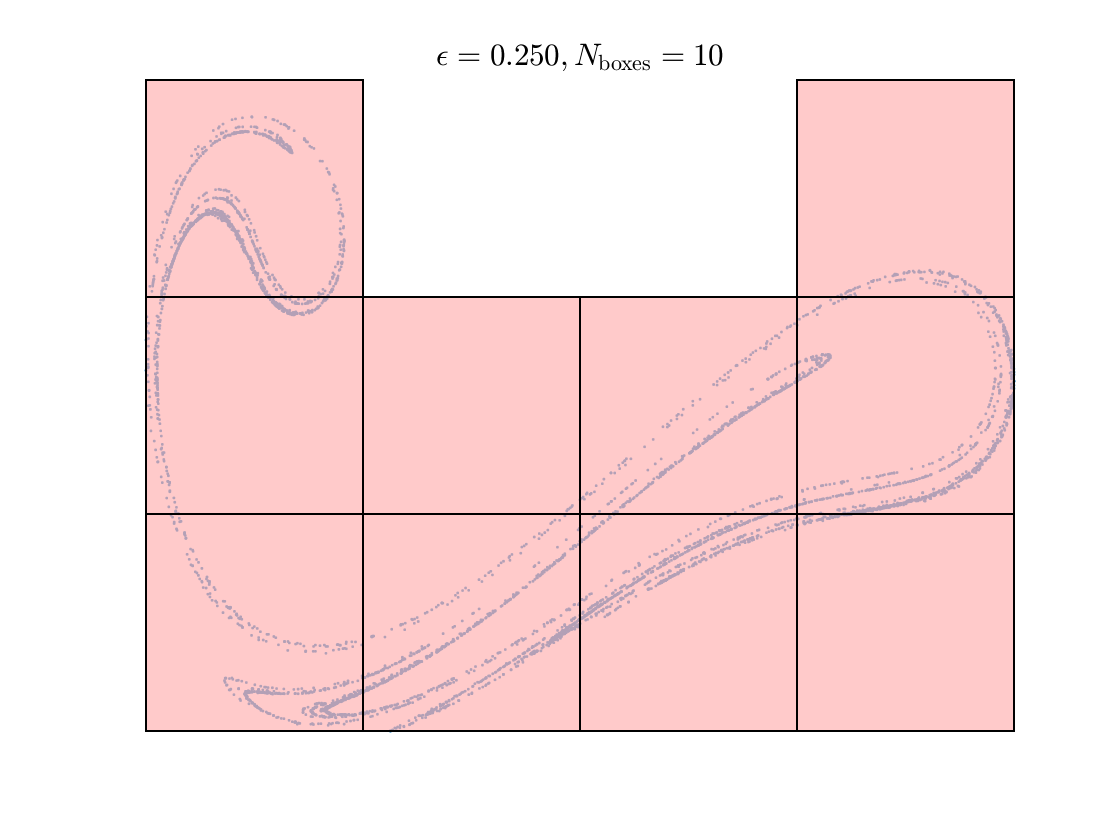

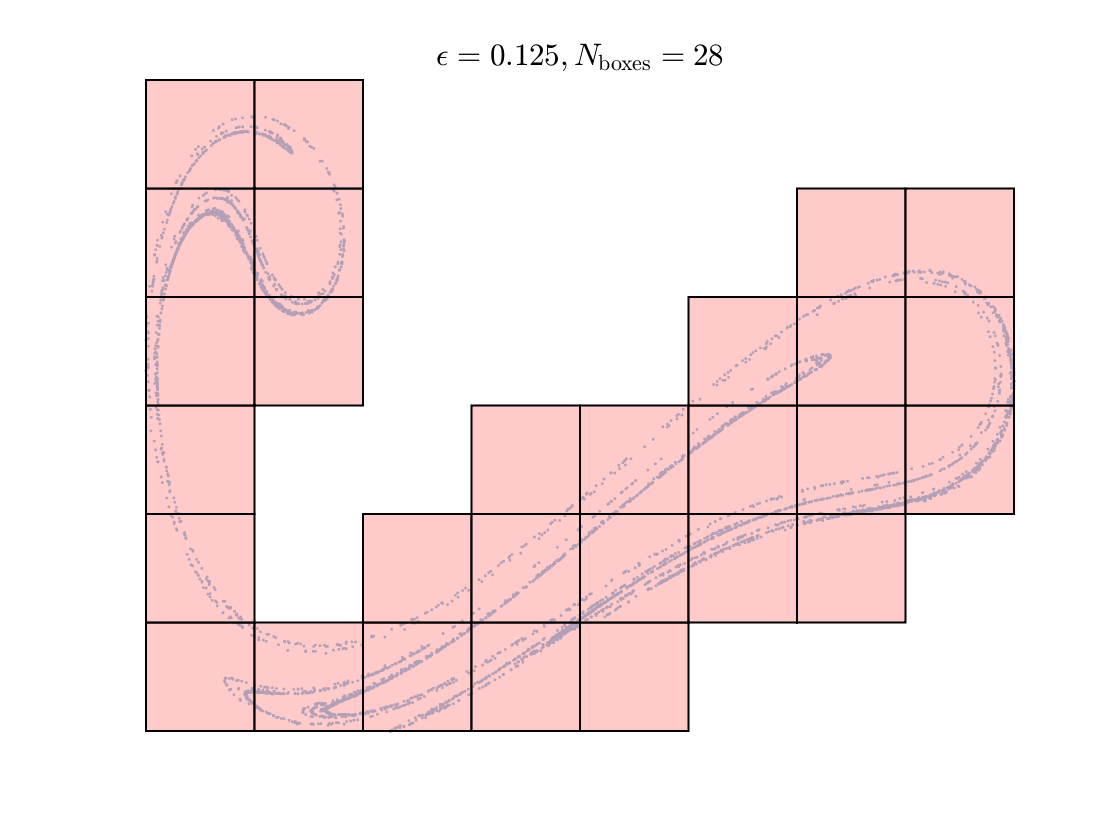

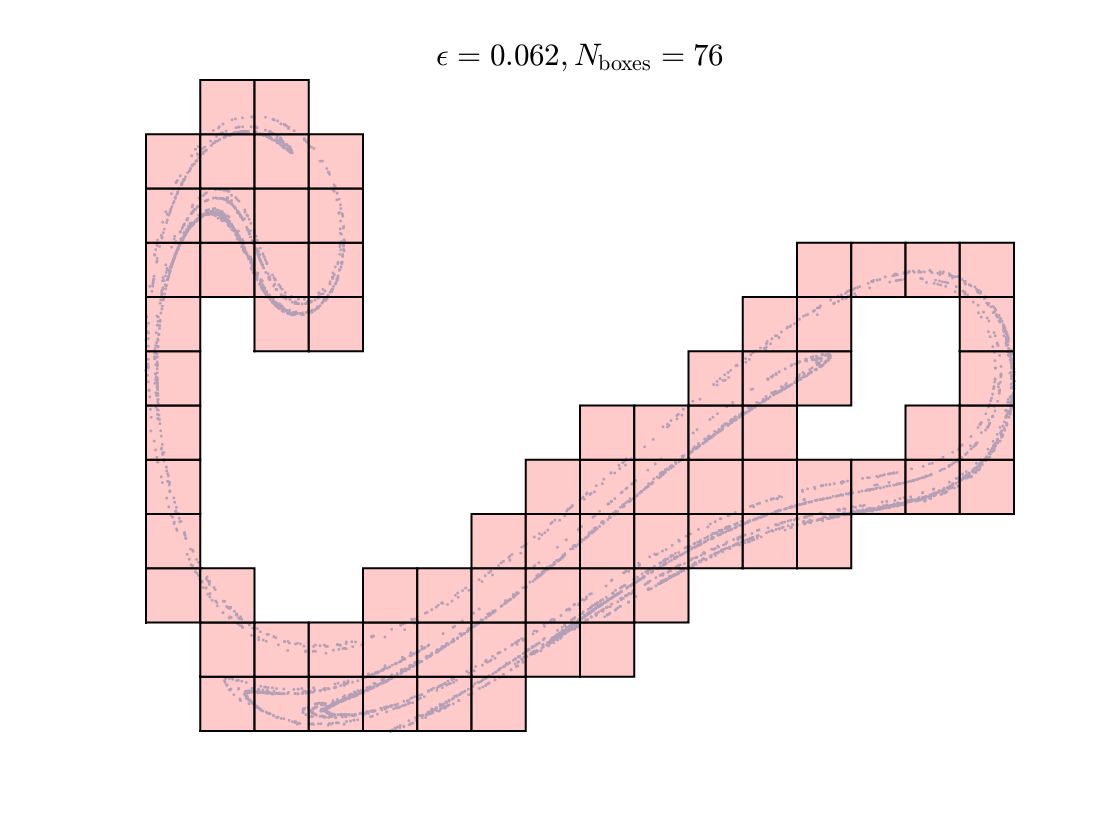

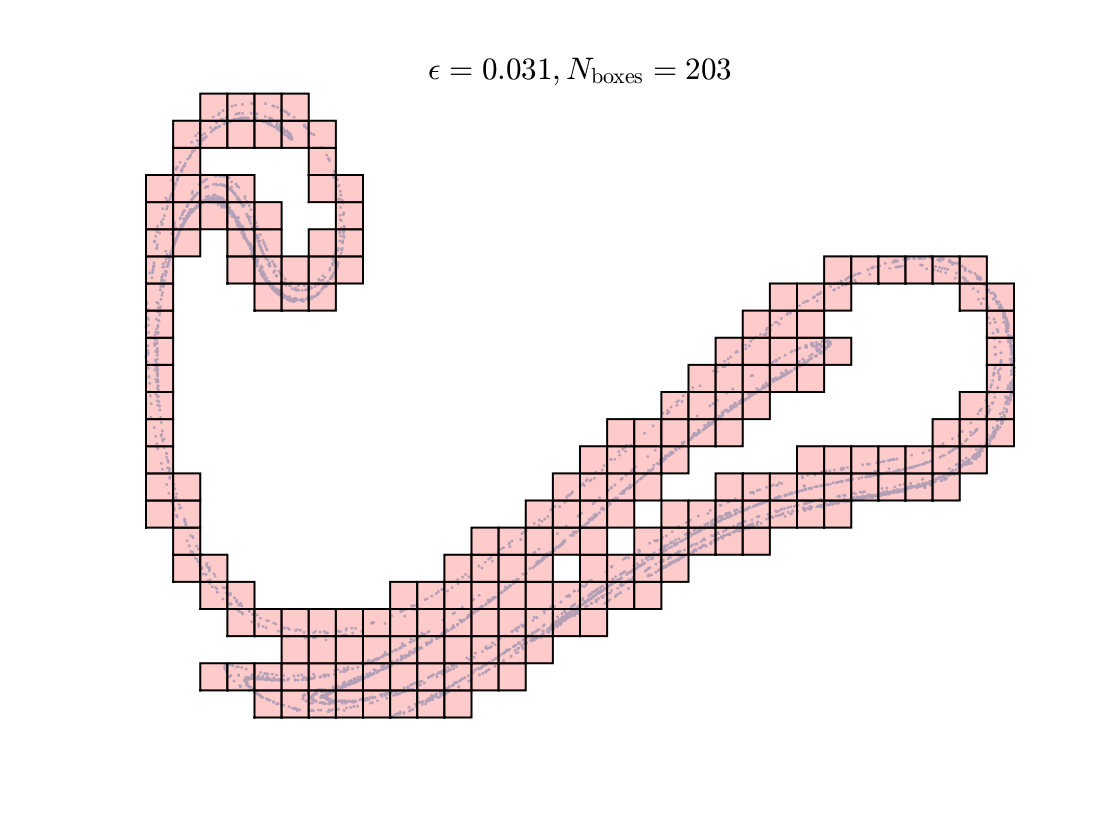

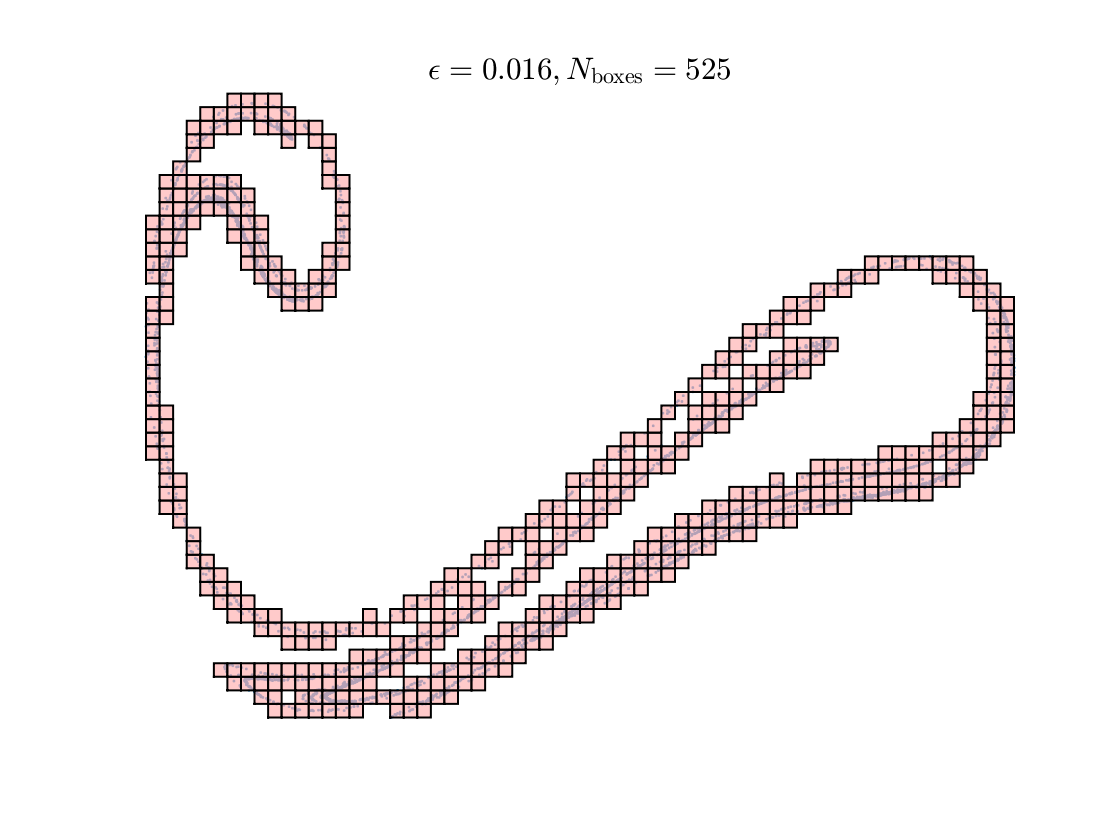

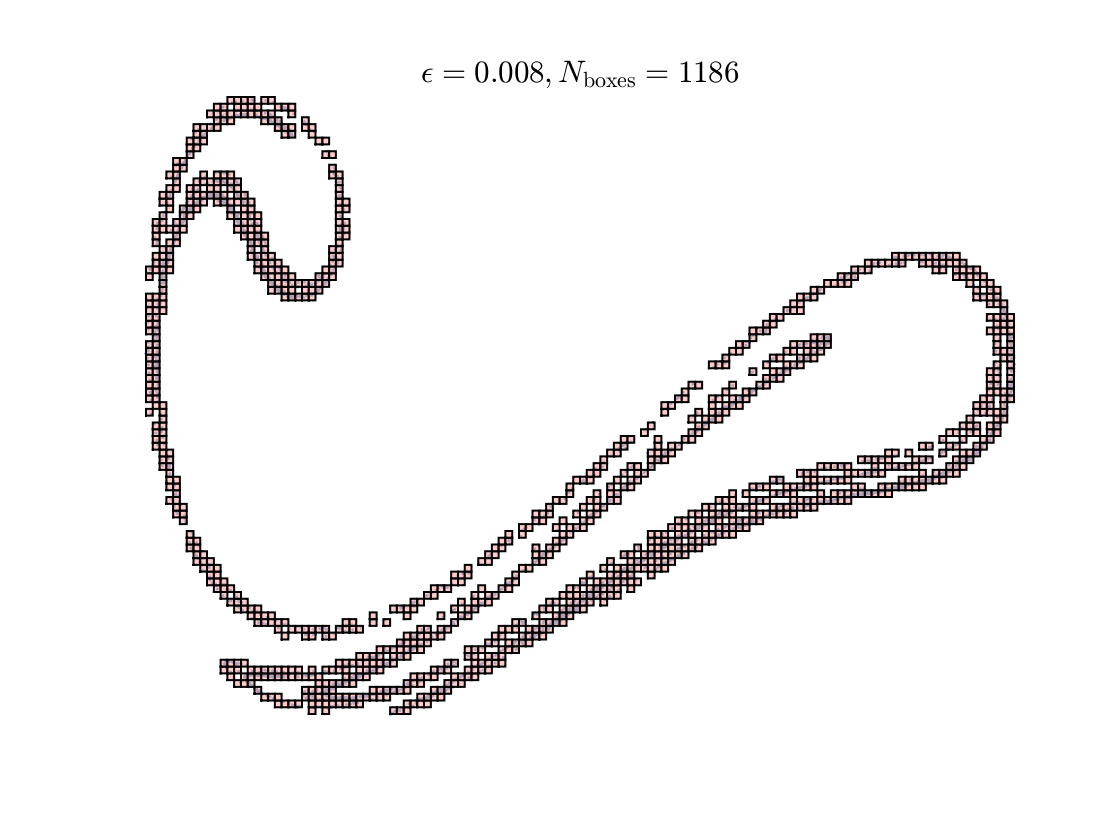

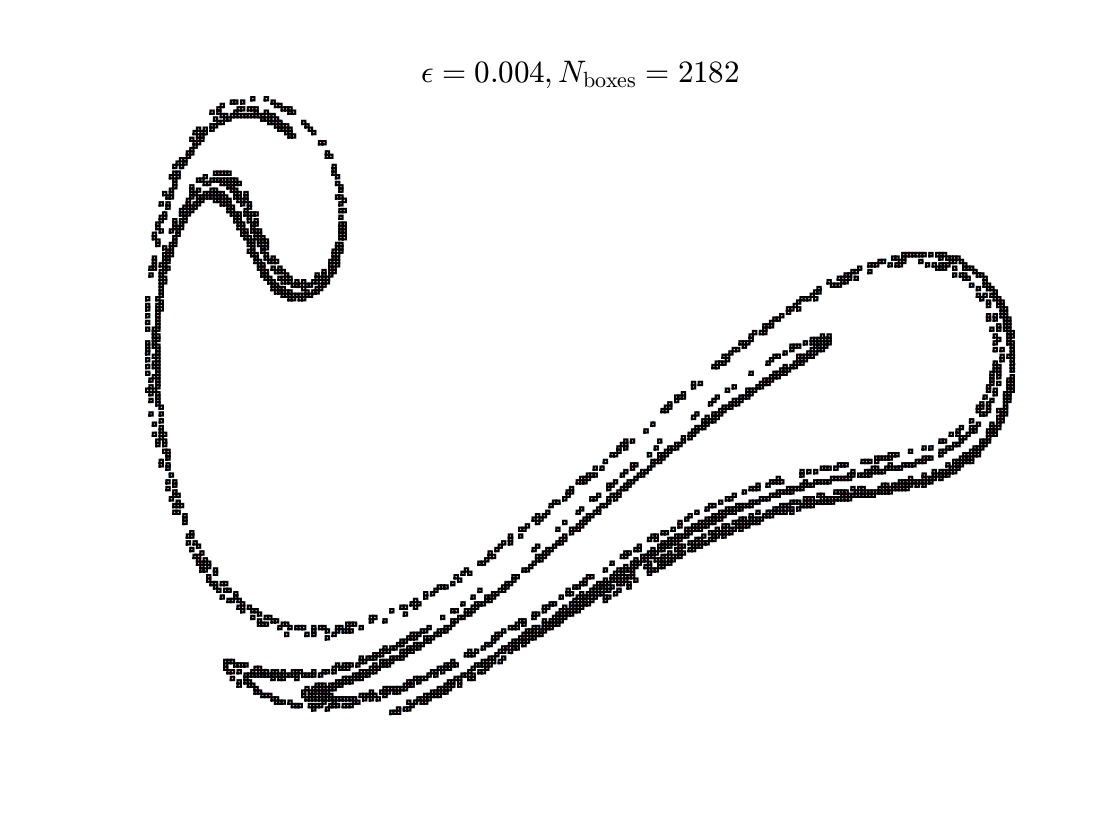

N=7;
epsilon=zeros(1,N);
Nboxes=zeros(1,N);
for k=1:N
    K=2^(k+1);
    [epsilon(k),Nboxes(k)]=countAndPlotBoxes(x,y,K);
end

## Processing the box-counting step

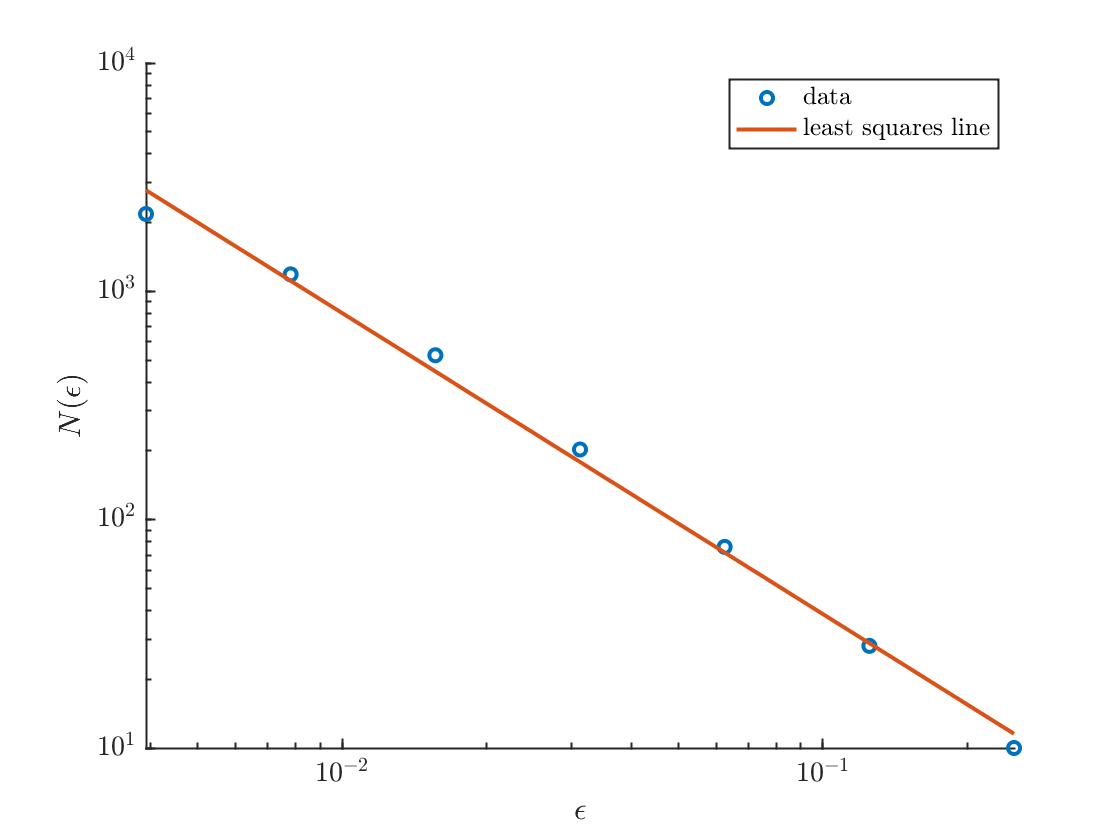

clf; hold on;
p=polyfit(log(epsilon),log(Nboxes),1);
dim=abs(p(1));

loglog(epsilon,Nboxes,'o',epsilon,exp(polyval(p,log(epsilon))));
set(gca,'xscale','log','yscale','log')

xlabel('$\epsilon$')
ylabel('$N(\epsilon)$')
legend('data','least squares line');

fprintf('The calculated dimension is %0.2f.\n',dim)

The calculated dimension is 1.32.


## Functions called

function dydt=doublewellODE(t,y,delta,F,omega)
dydt=zeros(2,1);
dydt(1) = y(2);
dydt(2) = -delta* y(2) + y(1)*(1-y(1)^2) + F*sin(omega*t);
end

function  [value, isterminal,direction]=doublewellEvent(t,~,omega)
value= sin(omega*t);
isterminal = 0;
direction = 1;
end

function [dx,Nboxes]=countAndPlotBoxes(x,y,K)

Scale and reposition the point set so that it fits in the box [0,1]x[0,1]

xmax=max(x); xmin=min(x); width=xmax-xmin;
ymax=max(y); ymin=min(y); height=ymax-ymin;
L=max(height,width);
y=(y-ymin)/L;
x=(x-xmin)/L;

 Define the grid size

dx=1/K;

Define a square box with unit-length sides

xbox=[0 1 1 0 0];
ybox=[0 0 1 1 0];

Plot the point set

figure;clf; hold on;
plot(x,y,'.','markersize',4)

#### The main step: 

Loop through all the sub-boxes of length and width `dx`. Set `isFilled(row,col)` to 1 if there is a point in the box, and to zero if not. If it is filled, plot  a pink square.

Note that this makes use of two built-in MATLAB commands

- `inpolygon` tests whether each point (x(row,col),y(row,col)) is in the box defined by `xv` and `yv`. This is vectorized and avoids the need for loops. (Not something you'd use very often.)

- `any `returns `1` if any elements of a matrix are nonzero and returns `0` otherwise. The `all` command is similar. These are very useful utilities.

isFilled=zeros(K,K);
for row=1:K
    for col=1:K
        xv=(xbox+col-1)*dx;
        yv=(ybox+row-1)*dx;
        isFilled(row,col)=any(inpolygon(x,y,xv,yv));
        if isFilled(row,col)
            patch(xv,yv,zeros(1,5),'facecolor',[1 .7 .7],'edgecolor','k','facealpha',0.7)
        end
    end
end
Nboxes=sum(isFilled(:)); %count the number of filled boxes
axis equal tight off
title(sprintf('$\\epsilon=%0.3f, N_{\\rm boxes}=%i$',dx,Nboxes))
end